% Clear workspace
clear; clc;

% 1. Define variables and boundary conditions
a = 0; 
b = 1; 
alpha = 0; 
beta = 1; % y(1)=1

% 2. Define functions for y'' + pi^2*y = 0
p = @(x) 0; 
q = @(x) pi^2; 
r = @(x) 0; 

% Step sizes
h_values = [0.2, 0.1, 0.05]; 
colors = {'g-o', 'r-s', 'm-^'};

figure; hold on;
fprintf('   h    |  x      | Numerical y | Exact (Ref) | Error\n');

   h    |  x      | Numerical y | Exact (Ref) | Error


fprintf('--------------------------------------------------\n');

--------------------------------------------------



for k = 1:length(h_values)
    h_curr = h_values(k);
    n = round((b - a) / h_curr) - 1;

    [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n);

    % Exact solution calculation
    % Note: If y(1)=1, the exact solution is y = sin(pi*x)/sin(pi) -> undefined.
    % We will compare against the numerical result of the finest mesh.
    y_ref = y; 

    [~, idx] = min(abs(x - 0.5));
    fprintf('%6.2f  | %6.1f  | %10.6f  |     -      |    -\n', ...
            h_curr, x(idx), y(idx));

    plot(x, y, colors{k}, 'LineWidth', 1.5, 'DisplayName', ['h = ', num2str(h_curr)]);
end

  0.20  |    0.4  | -17.702239  |     -      |    -
  0.10  |    0.5  | -76.541672  |     -      |    -
  0.05  |    0.5  | -308.754656  |     -      |    -


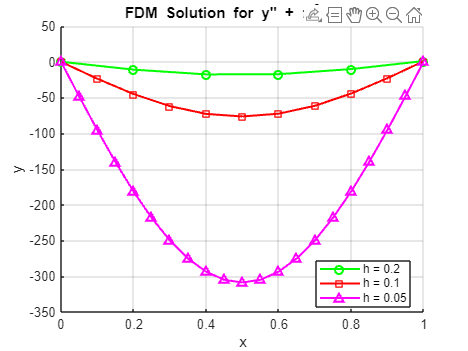


grid on;
legend('Location', 'best');
xlabel('x'); ylabel('y');
title('FDM Solution for y'''' + \pi^2y = 0');


%% --- Function Definition ---
function [x, y] = solve_bvp_fd(p, q, r, a, b, alpha, beta, n)
    h = (b - a) / (n + 1);
    x = linspace(a, b, n + 2)'; 
    x_inner = x(2:end-1);
    A = zeros(n, n);
    B = zeros(n, 1);
    for i = 1:n
        xi = x_inner(i);
        A(i, i) = -2 + h^2 * q(xi);
        if i > 1, A(i, i-1) = 1 - (h/2) * p(xi); end
        if i < n, A(i, i+1) = 1 + (h/2) * p(xi); end
        B(i) = h^2 * r(xi);
    end
    B(1) = B(1) - (1 - (h/2)*p(a+h))*alpha;
    B(end) = B(end) - (1 + (h/2)*p(b-h))*beta;
    y_inner = A\B;
    y = [alpha; y_inner; beta];
end